# LAB ASSIGNMENT #2 ECE480 Fall 2022

## Daniel VIjayasegar


%~~~~~~~ PROBLEM 1a ~~~~~~~
% Finding unknown parameters of difference eqn
close all;
clear;
clc;
disp('~~~ PROBLEM 1A ~~~')

~~~ PROBLEM 1A ~~~



syms a1 a2 b0 b1 b2;
eqn1 = b0 == 16.2

$$eqn1 = b_{0}=16.2000$$

eqn2 = b1-16.2*a1 == -3.42

$$eqn2 = b_{1}-16.2000\,a_{1}=-3.4200$$

eqn3 = b1+b2-12.78*a1-16.2*a2 == 0.38

$$eqn3 = b_{1}-16.2000\,a_{2}-12.7800\,a_{1}+b_{2}=0.3800$$

eqn4 = b1+b2-16.58*a1-12.78*a2 == 6.57

$$eqn4 = b_{1}-12.7800\,a_{2}-16.5800\,a_{1}+b_{2}=6.5700$$

eqn5 = b1+b2-22.77*a1-16.58*a2 == 9.06

$$eqn5 = b_{1}-16.5800\,a_{2}-22.7700\,a_{1}+b_{2}=9.0600$$

%eqn6 = b1+b2-25.26*a1-22.77*a2 == 6.29

[A,B] = equationsToMatrix([eqn1, eqn2, eqn3, eqn4, eqn5], [a1, a2, b0, b1, b2]);
X = linsolve(A,B);
disp('Unknown parameters: a1, a2, b0, b1, b2')

Unknown parameters: a1, a2, b0, b1, b2


a1=X(1,1)

$$a1 = -0.8997$$

a2=X(2,1)

$$a2 = 0.8103$$

b0=X(3,1)

$$b0 = 16.2000$$

b1=X(4,1)

$$b1 = -17.9950$$

b2=X(5,1)

$$b2 = 20.0036$$




%~~~~~~~ PROBLEM 1b-1 ~~~~~~~
% Plot x(n) and y(n), find energy of y(n)
% given x(n) = δ(n-1)
disp('~~~ PROBLEM 1B-1 ~~~')

~~~ PROBLEM 1B-1 ~~~




n = 0:1:50;
x = 1*(n>=1)*1.*(n==1);  %defining impulse @n=1

coefficients2 = [ 16.2 -17.995 20.0036];    %numerator
a = [ 1 -0.8997 0.8103];          %denominator
 
y_n = filter(coefficients2,a,x);      %apply x(n) input

disp('Energy of y(n): ')

Energy of y(n): 


E_yn=sum(abs(y_n).^ 2)   %energy of y(n)

E_yn = 400.1391

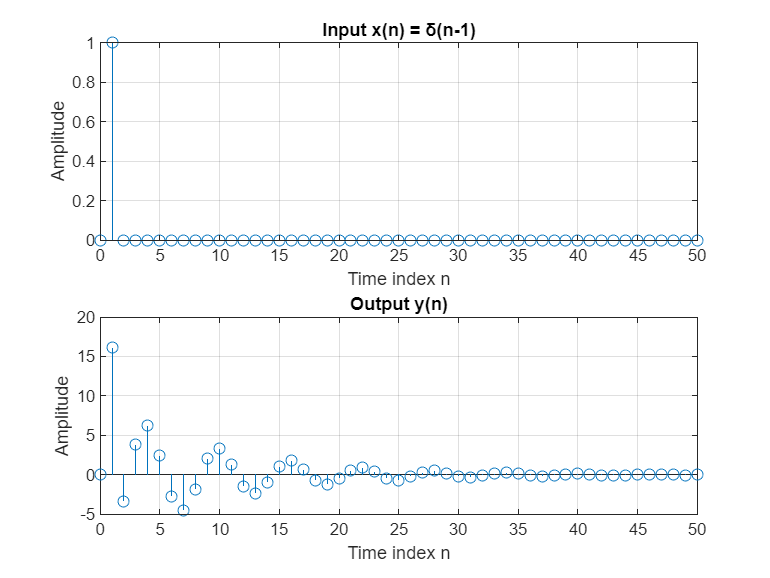



figure('Name','Problem 1b.1','NumberTitle','off');

subplot(211);
stem(n,x);
xlabel('Time index n');
ylabel('Amplitude');
grid on;
title('Input x(n) = δ(n-1)');

subplot(212);
stem(n,y_n);
xlabel('Time index n');
ylabel('Amplitude');
grid on;
title('Output y(n)');




%~~~~~~~ PROBLEM 1b-2 ~~~~~~~
% Plot x(n) and y(n), find energy of y(n)
% given x(n) = u(n-20)*δ(n-7)
disp('~~~ PROBLEM 1B-2 ~~~')

~~~ PROBLEM 1B-2 ~~~


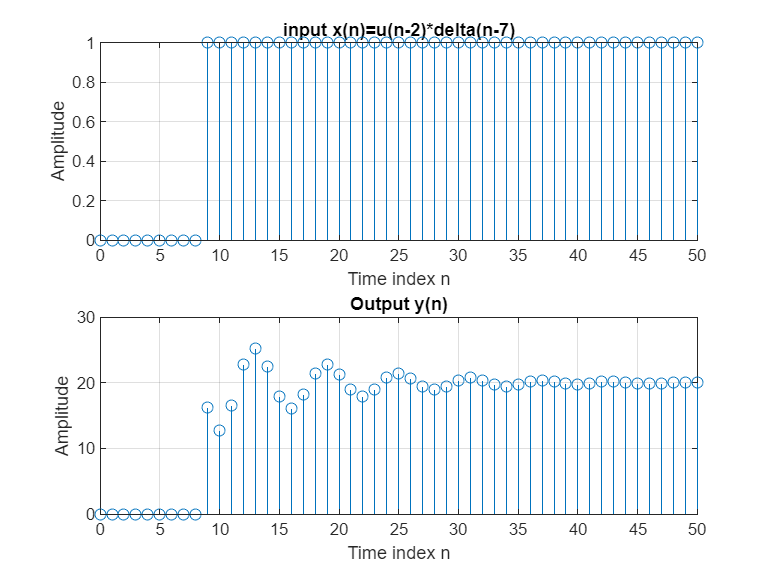




n = 0:1:50;
x_imp = 1*(n>=1)*1.*(n==7);   %define impulse
x_step=(n>=2);              %define step function
x_n=conv(x_imp,x_step);      %convolving impulse and step
x_n=x_n(1:51);               %trimming convolution result

figure('Name','Problem 1b.2','NumberTitle','off');
subplot(211);
stem(n,x_n);
xlabel('Time index n');
ylabel('Amplitude');
grid on;
title('input x(n)=u(n-2)*delta(n-7)');

y_n = filter(coefficients2,a,x_n);
subplot(212);
stem(n,y_n);
xlabel('Time index n');
ylabel('Amplitude');
grid on;
title('Output y(n)');


disp('Energy of case #2')

Energy of case #2


E_yn=sum(abs(y_n).^ 2)

E_yn = 1.6631e+04







%~~~~~~~ PROBLEM 1b-3 ~~~~~~~
% Plot x(n) and y(n), find energy of y(n)
% given x(n) = u(n)u(-n+23)
disp('~~~ PROBLEM 1B-3 ~~~')

~~~ PROBLEM 1B-3 ~~~


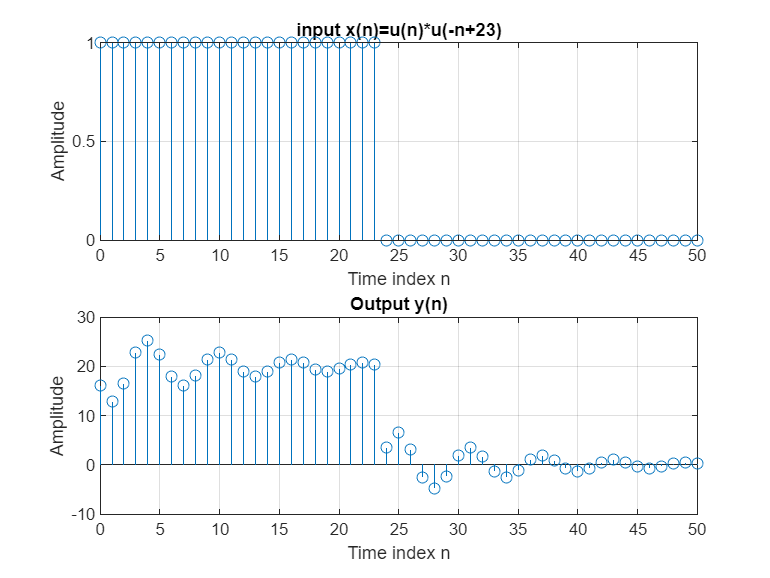


n = 0:1:50;
x_n = ones(size(n));
x_n(n>23) = 0;      %defining x(n)

figure('Name','Problem 1b.3','NumberTitle','off');
subplot(211);
stem(n,x_n);
xlabel('Time index n');
ylabel('Amplitude');
grid on;
title('input x(n)=u(n)*u(-n+23)');

y_n = filter(coefficients2,a,x_n);
subplot(212);
stem(n,y_n);
xlabel('Time index n');
ylabel('Amplitude');
grid on;
title('Output y(n)');


disp('Energy of case #3')

Energy of case #3


E_yn=sum(abs(y_n).^ 2)

E_yn = 9.5963e+03









%~~~~~~~ PROBLEM 1B-4 ~~~~~~~
disp('~~~ PROBLEM 1B-4 ~~~')

~~~ PROBLEM 1B-4 ~~~


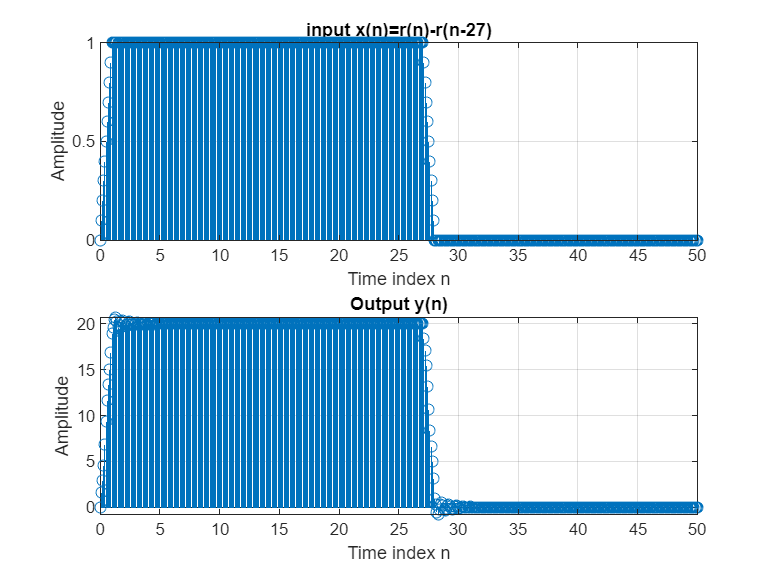

% Plot x(n) and y(n), find energy of y(n)
% given x(n) = r(n)-r(n-27)


n=0:0.1:50;
unit_step = n>=0;
ramp1=(n).*unit_step;
ramp1(n>1)=1;           %defining ramp1

ramp2=(n-27).*unit_step;
ramp2(n>28)=1;
ramp2(n<27)=0;          %defining ramp2

ramp = ramp1-ramp2;     %defining final ramp input


figure('Name','Problem 1b.4','NumberTitle','off');
subplot(211);
stem(n, ramp);
xlabel('Time index n');
ylabel('Amplitude');
grid on;
title('input x(n)=r(n)-r(n-27)');

y_n = filter(coefficients2,a,ramp);
subplot(212);
stem(n,y_n);
xlabel('Time index n');
ylabel('Amplitude');
grid on;
title('Output y(n)');



disp('Energy of case #4')

Energy of case #4


E_yn=sum(abs(y_n).^ 2)

E_yn = 1.0664e+05

%~~~~~~~ PROBLEM 1C ~~~~~~~
disp('~~~ PROBLEM 1C ~~~')

~~~ PROBLEM 1C ~~~


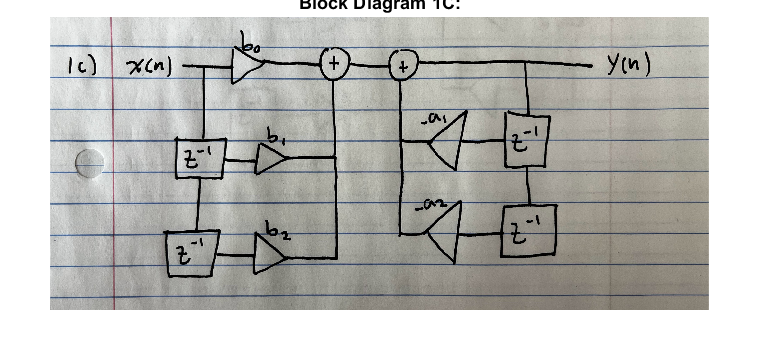


figure('Name','Problem 1C','NumberTitle','off');
imshow(imread("1c.jpg"))
title('Block Diagram 1C:')


disp('From the diagram:')

From the diagram:


disp('4 multiplications/sample at 10kHz sampling rate')

4 multiplications/sample at 10kHz sampling rate


disp('--> 40,000 multiplications/second')

--> 40,000 multiplications/second


%~~~~~~~ PROBLEM 2 ~~~~~~~
disp('~~~ PROBLEM 2 ~~~')

~~~ PROBLEM 2 ~~~


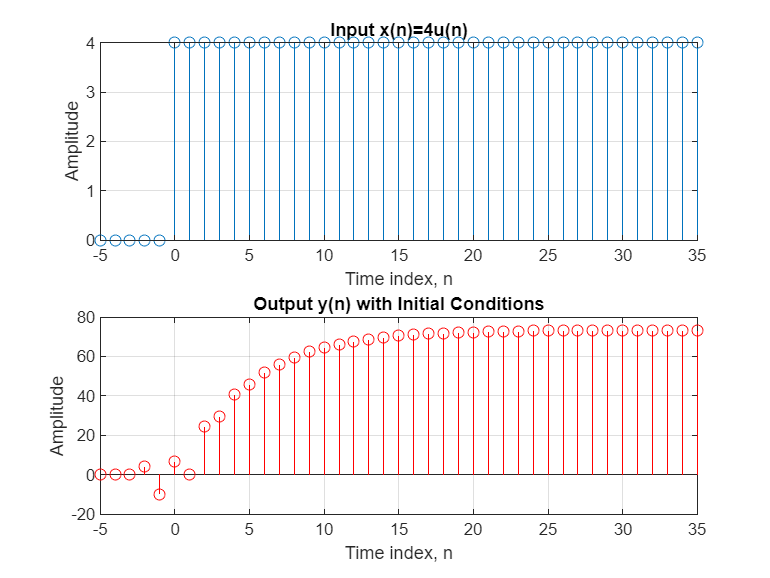


n=[-5:35]';  %domain

%set up input x(n)=4u(n)
x=zeros(size(n));
ind_x=find(n>=0);
x(ind_x)=4;

%finding initial condition indices
y=zeros(size(n));
ind_y1=find(n==-1);
ind_y2=find(n==-2);
ind_0=find(n==0);
len_n=length(n);

%setting initial conditions
y(ind_y1)=-10;  %y(-1)=-10
y(ind_y2)=4;    %y(-2)=4

%setting all output values with a loop
for i=ind_0:len_n
    y(i)=0.3*y(i-1) + 0.4*y(i-2) + 2*x(i) - 1.5*x(i-1) + 5*x(i-2);
end

figure('Name','Problem 2','NumberTitle','off');
subplot(211)
stem(n,x);
xlabel('Time index, n');
ylabel('Amplitude');
grid on
title('Input x(n)=4u(n)')

subplot(212)
stem(n,y,'r');
xlabel('Time index, n');
ylabel('Amplitude');
grid on
title('Output y(n) with Initial Conditions')

%~~~~~~~ PROBLEM 3A ~~~~~~~
disp('~~~ PROBLEM 3A ~~~')

~~~ PROBLEM 3A ~~~


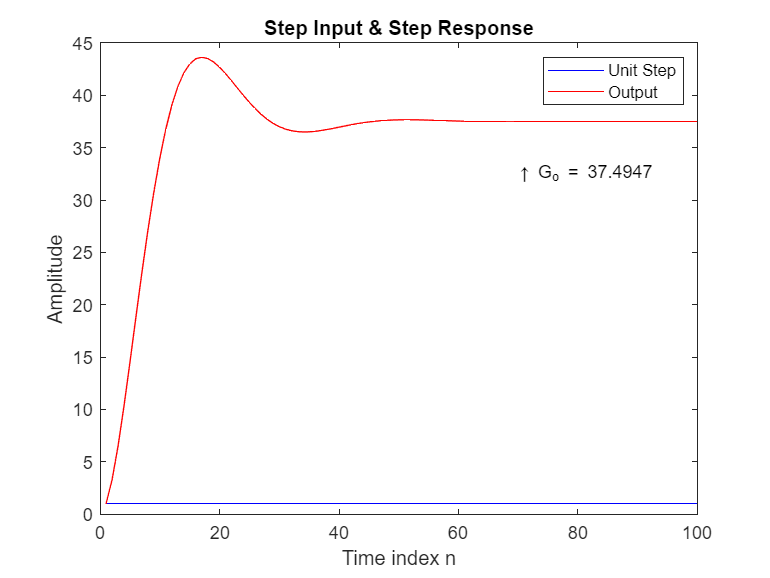


coefficients2 = [1, 0.5];            %numerator x(n) coefficients
a = [1, -1.77, 0.81];    %denominator y(n) coefficients

n = 100;              %domain length
x = ones([1,n]);      %unit step input 

y = filter(coefficients2,a,x); 
t = 1:1:n;


figure('Name','Problem 3A','NumberTitle','off');
plot(t,x,'b',t,y,'r');
legend('Unit Step','Output');
title('Step Input & Step Response');
xlabel('Time index n');
ylabel('Amplitude');

%calculate & label steady state output
G_o=mean(y(60:90));
G_o_str=num2str(G_o);
text(70,y(70)-5,['\uparrow G_o = ' num2str(G_o)]);

disp('Steady state output:')

Steady state output:


G_o

G_o = 37.4947



%~~~~~~~ PROBLEM 3B ~~~~~~~
disp('~~~ PROBLEM 3B ~~~')

~~~ PROBLEM 3B ~~~


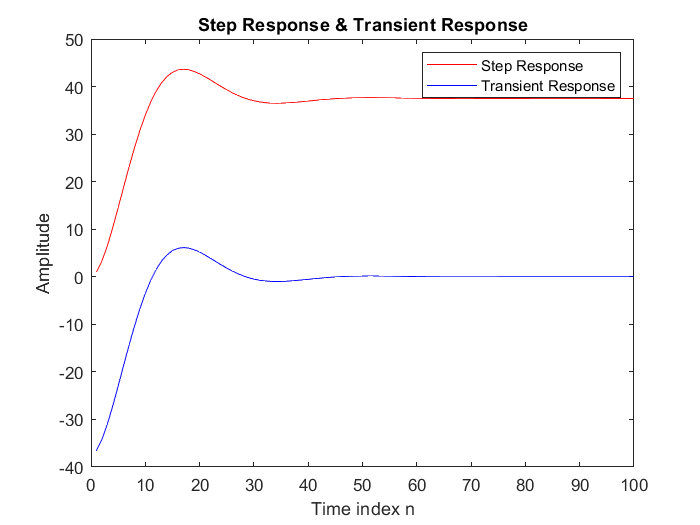

%calculate & plot transient response
y_transient=y-G_o;
figure('Name','Problem 3B','NumberTitle','off');
plot(t,y,'r',t,y_transient,'b')
legend('Step Response','Transient Response');
title('Step Response & Transient Response');
xlabel('Time index n');
ylabel('Amplitude');



%~~~~~~~ PROBLEM 3C & 3D ~~~~~~~
disp('~~~~~ Problem 3C & 3D ~~~~~')

~~~~~ Problem 3C & 3D ~~~~~


Energy_Transient = sum(abs(y_transient).^ 2);
disp('Energy of Transient Response:')

Energy of Transient Response:


Energy_Transient

Energy_Transient = 5.7540e+03


SSO_Ind = find(abs(y-G_o) <= 0.5e-2, 1, 'first');
disp(['System reaches SSO at sample number: ' num2str(SSO_Ind)])

System reaches SSO at sample number: 63


%~~~~~~~ PROBLEM 4A ~~~~~~~
disp('~~~ PROBLEM 4A ~~~')

~~~ PROBLEM 4A ~~~


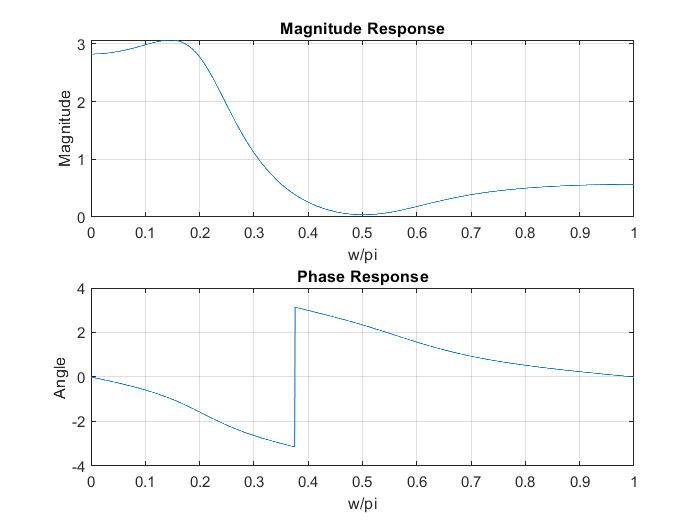


%define system coefficients
a = [1, -0.9051, 0.598, -0.29, 0.1958];     %numerator y(n) coefficients
coefficients2 = [0.414, 0 , 0.862, 0, 0.414];            %denominator x(n) coefficients

w=0:pi/1000:pi;
H=freqz(coefficients2,a,w);   %freq response


figure('Name','Problem 4a','NumberTitle','off');
subplot(211);
plot(w/pi,abs(H));
grid on;
xlabel('w/pi');
ylabel('Magnitude');
title('Magnitude Response');

subplot(212);
plot(w/pi,angle(H));
grid on;
xlabel('w/pi');
ylabel('Angle');
title('Phase Response');


disp("From the magnitude response, this is a LOW PASS filter")

From the magnitude response, this is a LOW PASS filter






%~~~~~~~ PROBLEM 4B ~~~~~~~
%Response of the system for x(n)
disp('~~~ PROBLEM 4B ~~~')

~~~ PROBLEM 4B ~~~


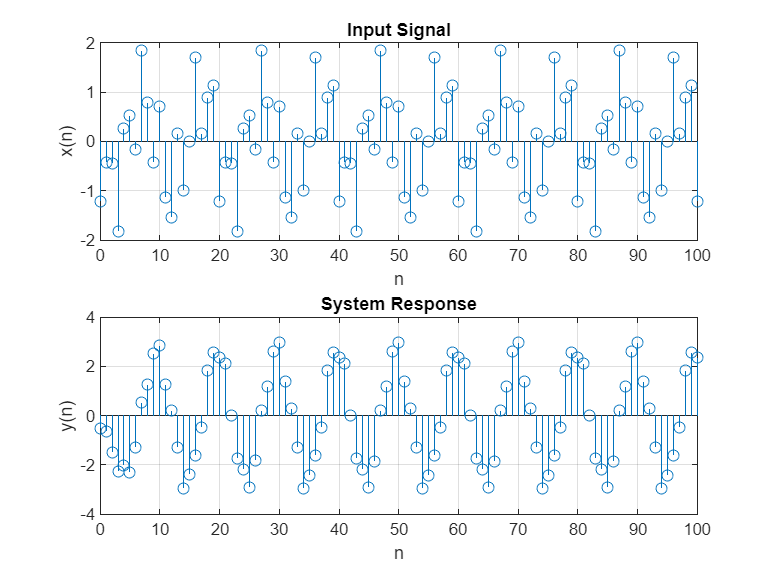


w1=0.25*pi;
w2=0.45*pi;
n=0:1:100;

x=(2*cos((w1*n)+(pi/6))).*cos((w2*n)+(3*pi/4)).*(n>=0);
y=filter(coefficients2,a,x);

figure('Name','Problem 4b','NumberTitle','off');
subplot(211);
stem(n,x);
grid on;
xlabel('n');
ylabel('x(n)');
title('Input Signal');

subplot(212);
stem(n,y);
grid on;
xlabel('n');
ylabel('y(n)');
title('System Response');



%~~~~~~~ PROBLEM 4G ~~~~~~~
%Frequency response of input and output
disp('~~~ PROBLEM 4G ~~~')

~~~ PROBLEM 4G ~~~


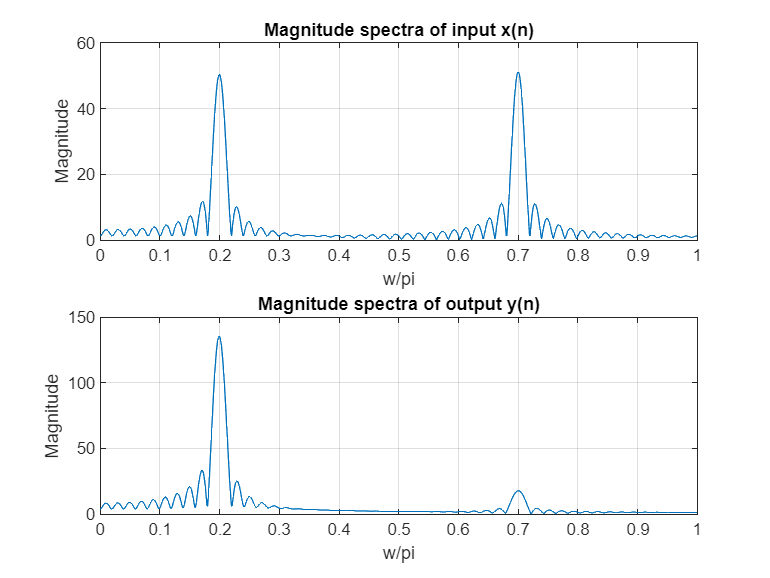


X_in=freqz(x,1,w);
figure('Name','Problem 4g','NumberTitle','off');
subplot(211);
plot(w/pi,abs(X_in));
grid on;
xlabel('w/pi')
ylabel('Magnitude');
title('Magnitude spectra of input x(n)');

Y_out=freqz(y,1,w);
subplot(212);
plot(w/pi,abs(Y_out));
grid on;
xlabel('w/pi')
ylabel('Magnitude');
title('Magnitude spectra of output y(n)');

disp(['From the magnitude spectra, it seems that the system y(n) ' ...
    'attenuates the higher of the two dominant frequencies in the input '])

From the magnitude spectra, it seems that the system y(n) attenuates the higher of the two dominant frequencies in the input 






%~~~~~~~ PROBLEM 4C ~~~~~~~
%steady state response for step input
disp('~~~ PROBLEM 4C ~~~')

~~~ PROBLEM 4C ~~~


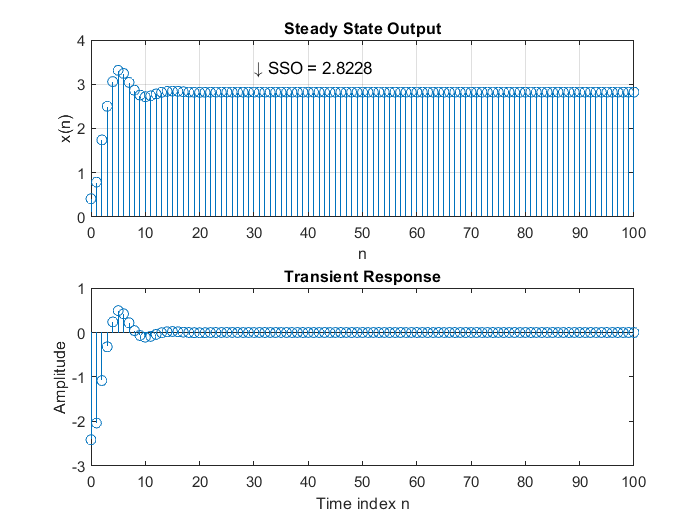

x=(n>=0);   %input
y=filter(coefficients2,a,x);
SSO=mean(y(30:70));

figure('Name','Problem 4c','NumberTitle','off');
subplot(211)
stem(n,y);
grid on;
xlabel('n');
ylabel('x(n)');
title('Steady State Output');
text(30,3.4,['\downarrow SSO = ' num2str(SSO)]);

%calculate & plot transient response
y_transient=y-SSO;
subplot(212);
stem(n,y_transient);
title('Transient Response');
xlabel('Time index n');
ylabel('Amplitude');


disp('Steady State Output: ')

Steady State Output: 


SSO

SSO = 2.8228


%~~~~~~~ PROBLEM 4D ~~~~~~~
%calculate transient time
disp('~~~ PROBLEM 4D ~~~')

~~~ PROBLEM 4D ~~~


SSO_Ind = find(abs(y-SSO) <= 0.5e-3, 1, 'first');
disp(['System reaches SSO at sample number ' num2str(SSO_Ind)]);

System reaches SSO at sample number 19


f_samp=1000;
T_samp=1/f_samp;
Transient_time=SSO_Ind*T_samp*1000;
disp(['Transient time = ' num2str(SSO_Ind) ' milliseconds']);

Transient time = 19 milliseconds






%~~~~~~~ PROBLEM 4E 4F ~~~~~~~
%find energy of transient signal
disp('~~~ PROBLEM 4E & 4F ~~~')

~~~ PROBLEM 4E & 4F ~~~


disp('Energy of Transient Response: ')

Energy of Transient Response: 


Energy_Transient = sum(abs(y_transient).^ 2)

Energy_Transient = 11.7616

%~~~~~~~ PROBLEM 5A ~~~~~~~
disp('~~~ PROBLEM 5A ~~~')

~~~ PROBLEM 5A ~~~



syms b0 b1 b2 b3;

y21=79.9812; y20=20.2859; y19=-8.0847; y18=27.2908;
y17=104.6725; y16=136.7383; y15=64.1622; y14=-25.7555;
y13=-44.6275; y12=-34.9304; y11=-30.0383; y10=-19.2318;

x21=-87.5874; x20=78.7346; x19=94.0704; x18=187.7865;
x17=-103.5985; x16=42.8623; x15=-31.5772; x14=95.9401;
x13=242.4461; x12=103.5976; x11=-183.5859; x10=35.0063;

eqn1 = y21 == b0*x21 + b1*x20 + b2*x19 + b3*x18 + b2*x17 + b1*x16 + b0*x15;
eqn2 = y20 == b0*x20 + b1*x19 + b2*x18 + b3*x17 + b2*x16 + b1*x15 + b0*x14;
eqn3 = y19 == b0*x19 + b1*x18 + b2*x17 + b3*x16 + b2*x15 + b1*x14 + b0*x13;
eqn4 = y18 == b0*x18 + b1*x17 + b2*x16 + b3*x15 + b2*x14 + b1*x13 + b0*x12;



[A,C] = equationsToMatrix([eqn1, eqn2, eqn3, eqn4], [b0, b1, b2, b3])

$$A = \left(\begin{array}{cccc} 119.1646 & -121.5969 & 9.5281 & -187.7865\\ -174.6747 & -62.4932 & -230.6488 & 103.5985\\ -336.5165 & -283.7266 & 135.1757 & -42.8623\\ -291.3841 & -138.8476 & -138.8024 & 31.5772 \end{array}\right)$$

$$C = \left(\begin{array}{c} -79.9812\\ -20.2859\\ 8.0847\\ -27.2908 \end{array}\right)$$

sympref('FloatingPointOutput',true)

ans = logical
   1


coefficients1 = linsolve(A,C)

$$coefficients1 = \left(\begin{array}{c} -0.0127\\ 0.0515\\ 0.2623\\ 0.3978 \end{array}\right)$$



fprintf("\n~~~~~ Problem 5A ~~~~~\n");


~~~~~ Problem 5A ~~~~~


disp('The coefficients b0, b1, b2, b3 are as follows:');

The coefficients b0, b1, b2, b3 are as follows:


b0=coefficients1(1)

$$b0 = -0.0127$$

b1=coefficients1(2)

$$b1 = 0.0515$$

b2=coefficients1(3)

$$b2 = 0.2623$$

b3=coefficients1(4)

$$b3 = 0.3978$$

b4=coefficients1(3)

$$b4 = 0.2623$$

b5=coefficients1(2)

$$b5 = 0.0515$$

b6=coefficients1(1)

$$b6 = -0.0127$$




disp(['The difference equation is: ']);

The difference equation is: 


disp('y(n) = -0.0127x(n) + 0.0515x(n-1) + 0.2623x(n-2) + 0.3978x(n-3) + 0.2623x(n-4) + 0.0515x(n-5) - 0.0127x(n-6)');

y(n) = -0.0127x(n) + 0.0515x(n-1) + 0.2623x(n-2) + 0.3978x(n-3) + 0.2623x(n-4) + 0.0515x(n-5) - 0.0127x(n-6)


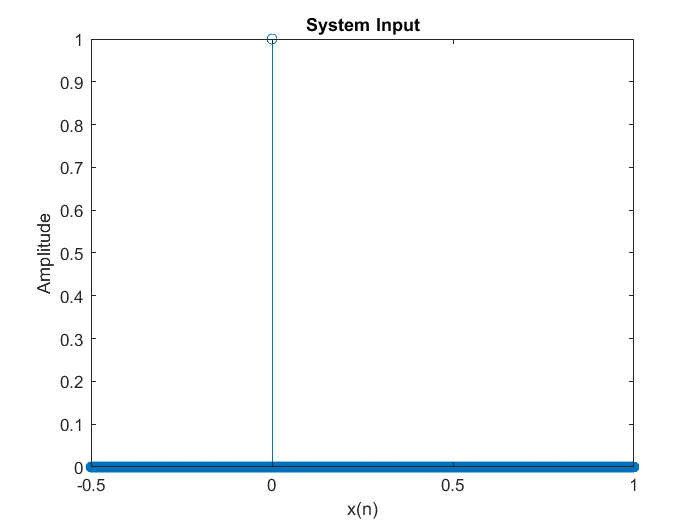



%Problem 5B: plotting impulse response
b = [-0.0127, 0.0515, 0.2623, 0.3978, 0.2623, 0.0515, -0.0127];       %numerator  x(n)
a = [1];                                            %denominator y(n)
n=(-0.5:0.001:1)';   %domain
x = n==0;            %unit impulse input
y = filter(b,a,x);   %putting unit impulse through filter


figure('Name','Problem 5B','NumberTitle','off');
stem(n,x);
title('System Input');
xlabel('x(n)');
ylabel('Amplitude');

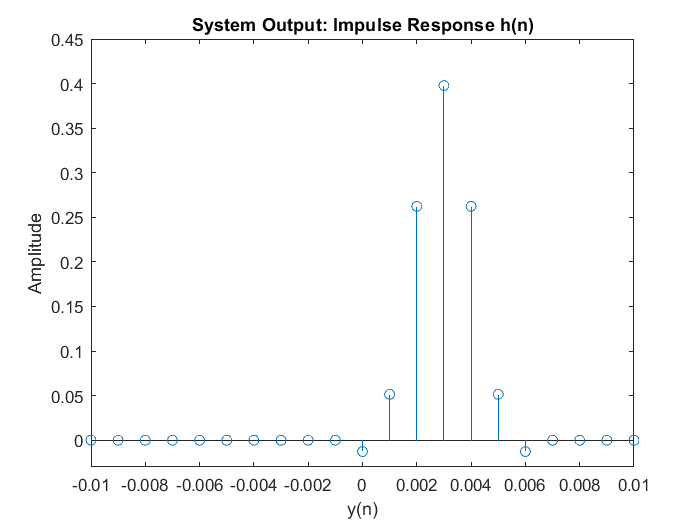


figure('Name','Problem 5B','NumberTitle','off');
stem(n,y);
title('System Output: Impulse Response h(n)');
xlabel('y(n)');
ylabel('Amplitude');
xlim([-0.01 0.01]);
ylim([-0.03 0.45]);

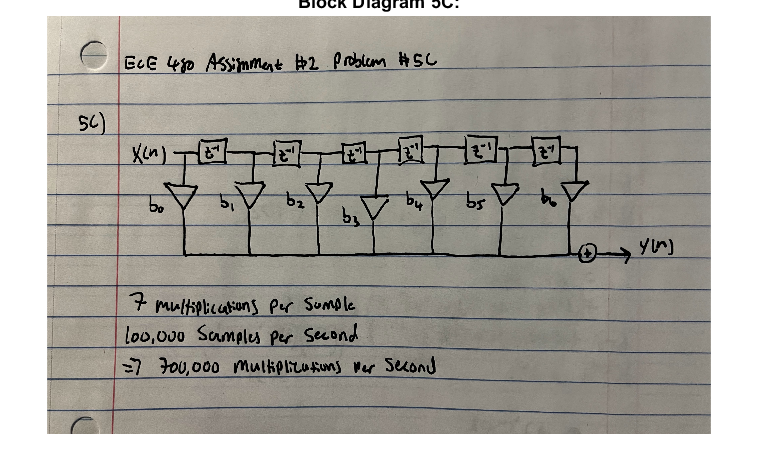




% Problem 5C: Draw the block diagram, find number of multiplications/sec
figure('Name','Problem 5C','NumberTitle','off');
imshow(imread("hw2_5c.jpg"))
title('Block Diagram 5C:')


disp('From the block diagram:')

From the block diagram:


disp('7 multiplications/sample')

7 multiplications/sample


disp('fs = 100,000 samples/second')

fs = 100,000 samples/second


disp('Therefore --> 700,000 multiplications/second')

Therefore --> 700,000 multiplications/second


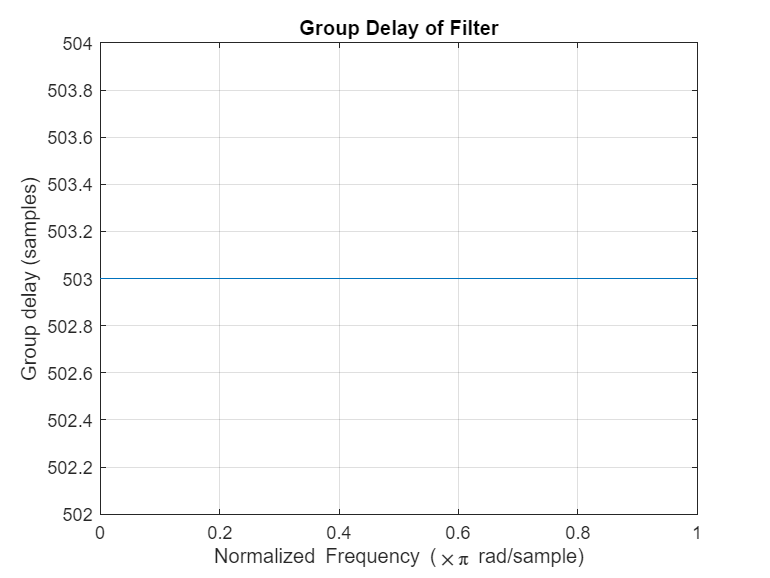



%Problem 5D: Finding group delay
figure('Name','Problem 5D','NumberTitle','off');
grpdelay(y)
title('Group Delay of Filter');

disp('From the plot, we can see the group delay is constant')

From the plot, we can see the group delay is constant


disp('The group delay value is: 503')

The group delay value is: 503


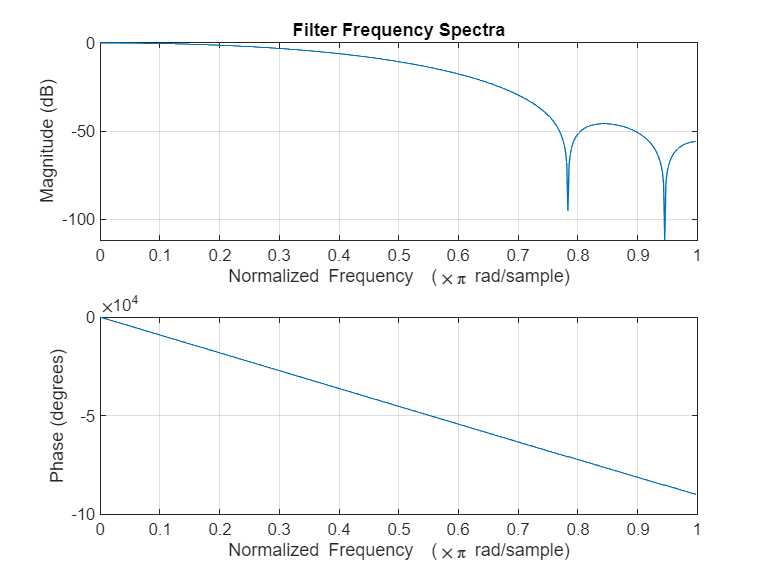



%Problem 5E: Plot frequency response
figure('Name','Problem 5E','NumberTitle','off');
freqz(y)
title('Filter Frequency Spectra');



%Problem 5F: Find the 3db bandwidth
disp('By inspection of the magnitude spectra plot:')

By inspection of the magnitude spectra plot:


disp('The 3db frequency is 0 — 0.295pi rad/sample')

The 3db frequency is 0 — 0.295pi rad/sample


%~~~~~~~ PROBLEM 6 ~~~~~~~
disp('~~~ PROBLEM 6 ~~~')

~~~ PROBLEM 6 ~~~



%Problem 6A
syms a1 a2 a3 b1 b2 b3;

y0=1.1544; y1=2.1612; y2=3.1216; y3=3.2416;
y4=1.3917; y5=2.2752; y6=6.1046;

x0=7.254; x1=-0.6305; x2=7.1474; x3=-2.0497;
x4=-1.2414; x5=14.897; x6=14.0903;

b0=0.159;
eqn1 = y1 == a1*y0 + b0*x1 + b1*x0;
eqn2 = y2 == a1*y1 + a2*y0 + b0*x2 + b1*x1 + b2*x0;
eqn3 = y3 == a1*y2 + a2*y1 + a3*y0 + b0*x3 + b1*x2 + b2*x1 + b3*x0;
eqn4 = y4 == a1*y3 + a2*y2 + a3*y1 + b0*x4 + b1*x3 + b2*x2 + b3*x1;
eqn5 = y5 == a1*y4 + a2*y3 + a3*y2 + b0*x5 + b1*x4 + b2*x3 + b3*x2;
eqn6 = y6 == a1*y5 + a2*y4 + a3*y3 + b0*x6 + b1*x5 + b2*x4 + b3*x3;


[A,C] = equationsToMatrix([eqn1, eqn2, eqn3, eqn4, eqn5, eqn6], [a1, a2, a3, b1, b2, b3]);
coefficients2 = linsolve(A,C);


fprintf("\n~~~~~ Problem 6A ~~~~~\n");


~~~~~ Problem 6A ~~~~~


disp('The coefficient b0 was calculated by hand: b0=0.159');

The coefficient b0 was calculated by hand: b0=0.159


disp('The coefficients a1, a2, a3, & b0, b1, b2, b3 are as follows:');

The coefficients a1, a2, a3, & b0, b1, b2, b3 are as follows:


a1=coefficients2(1)

$$a1 = 1.1571$$

a2=coefficients2(2)

$$a2 = -1.1822$$

a3=coefficients2(3)

$$a3 = 0.4511$$

b0

b0 = 0.1590

b1=coefficients2(4)

$$b1 = 0.1276$$

b2=coefficients2(5)

$$b2 = 0.1282$$

b3=coefficients2(6)

$$b3 = 0.1597$$

disp('The difference equation is: ');

The difference equation is: 


disp('y(n) = 1.1571*y(n-1)-1.1822*y(n-2)+0.4511*y(n-3)+0.159*x(n)+0.1276*x(n-1)+0.1282*x(n-2)+0.1597*x(n-3)');

y(n) = 1.1571*y(n-1)-1.1822*y(n-2)+0.4511*y(n-3)+0.159*x(n)+0.1276*x(n-1)+0.1282*x(n-2)+0.1597*x(n-3)





disp('~~~ PROBLEM 6B ~~~')

~~~ PROBLEM 6B ~~~


b = [-0.55,-3.74,-18.99,-368.17,-1530,-6300];       %numerator  x(n)
a = [1];                                       %denominator y(n)
n=[-0.5:0.001:1]';                                %domain
x = n==0;                                   %unit impulse input
y = filter(b,a,x)

y = 1.0e+03 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0




figure('Name','Problem 6B','NumberTitle','off');
stem(n,x);
title('System Input');
xlabel('x(n)');
ylabel('Amplitude');

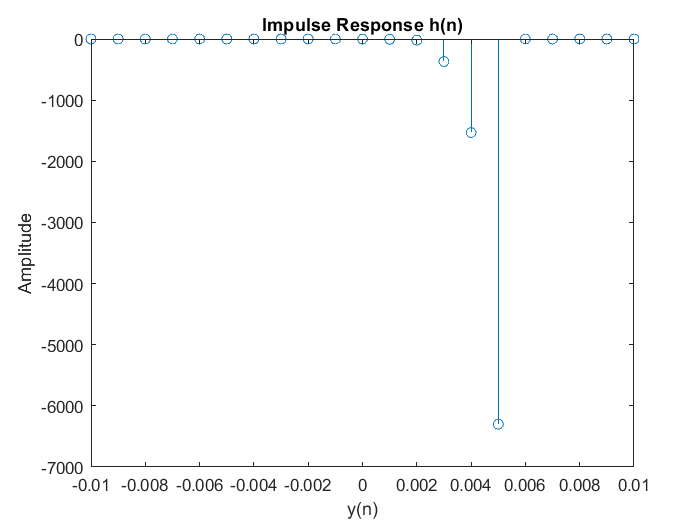


figure('Name','Problem 6B','NumberTitle','off');
stem(n,y);
title('Impulse Response h(n)');
xlabel('y(n)');
ylabel('Amplitude');
xlim([-0.01 0.01])

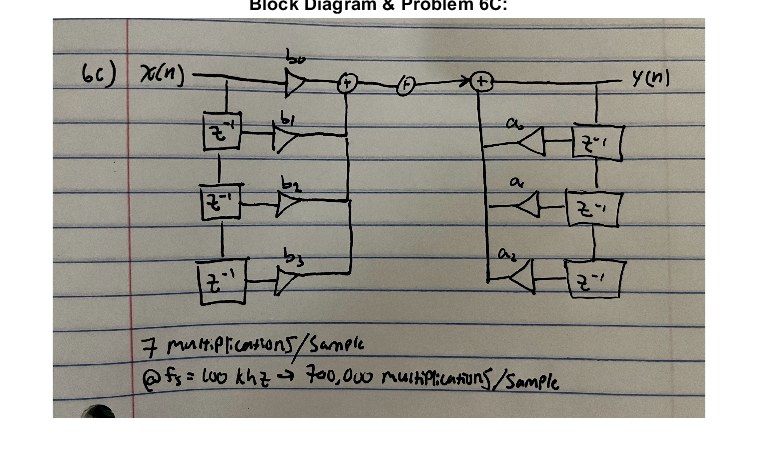




%Problem 6C: Block diagram
figure('Name','Problem 6C','NumberTitle','off');
imshow(imread("hw2_6c.jpg"))
title('Block Diagram & Problem 6C:')

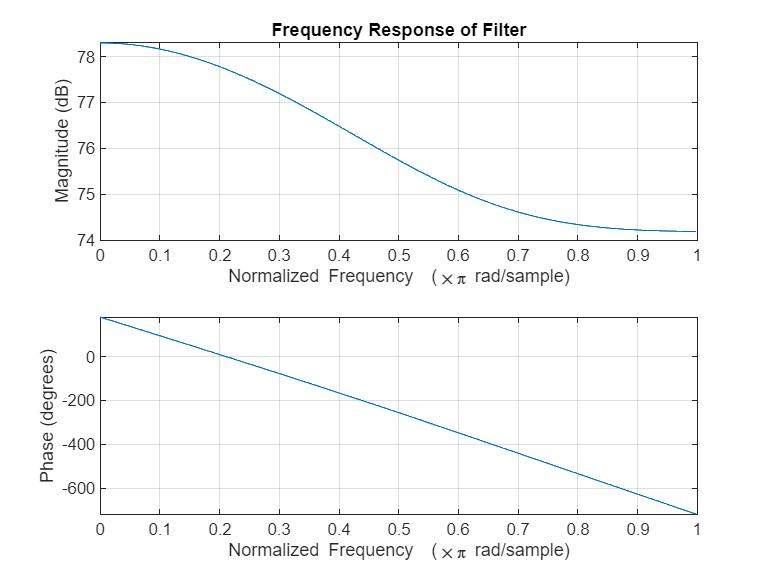




%Problem 6E: Frequency Response Plot
figure('Name','Problem 6B','NumberTitle','off');
freqz(b,a)
title('Frequency Response of Filter');


%Problem 6F: Find the 3db bandwidth
disp('By inspection of the magnitude spectra plot:')

By inspection of the magnitude spectra plot:


disp('The attenuation never reaches -3db')

The attenuation never reaches -3db


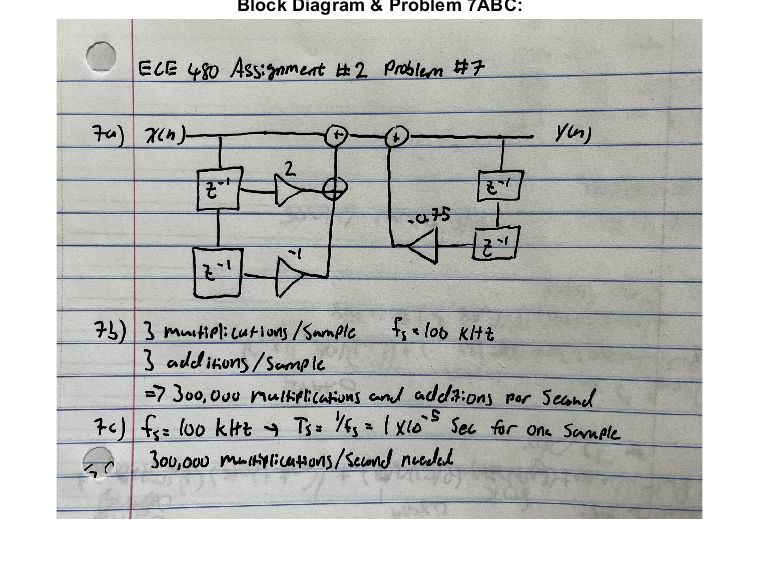

%Problem 7

% Problem 7A: Draw the block diagram
figure('Name','Problem 7ABC','NumberTitle','off');
imshow(imread("hw2_7abc.jpg"))
title('Block Diagram & Problem 7ABC:')

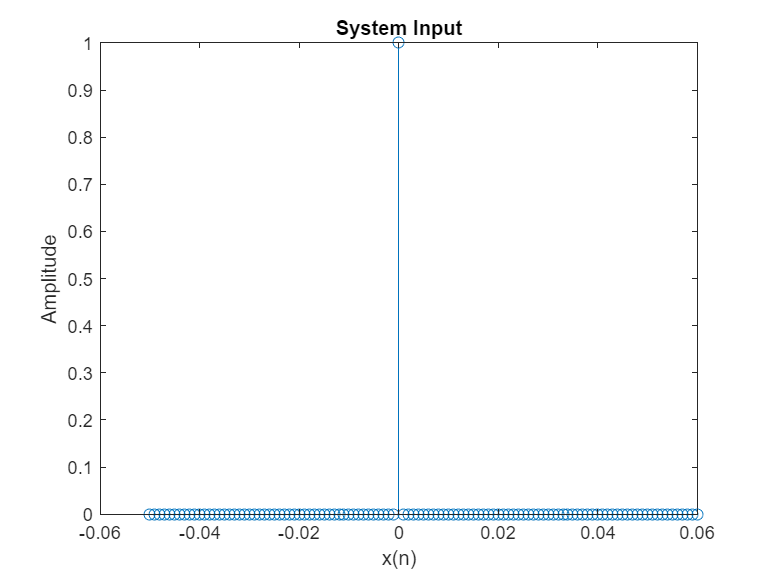




%Problem 7D: Impulse Response
b = [1,2,-1];       %numerator  x(n)
a = [1,0,-0.75];    %denominator y(n)

n=[-0.05:0.001:0.06]';  %domain

x = n==0;  %unit impulse input
y = filter(b,a,x); 

figure('Name','Problem 7D','NumberTitle','off');
stem(n,x);
title('System Input');
xlabel('x(n)');
ylabel('Amplitude');

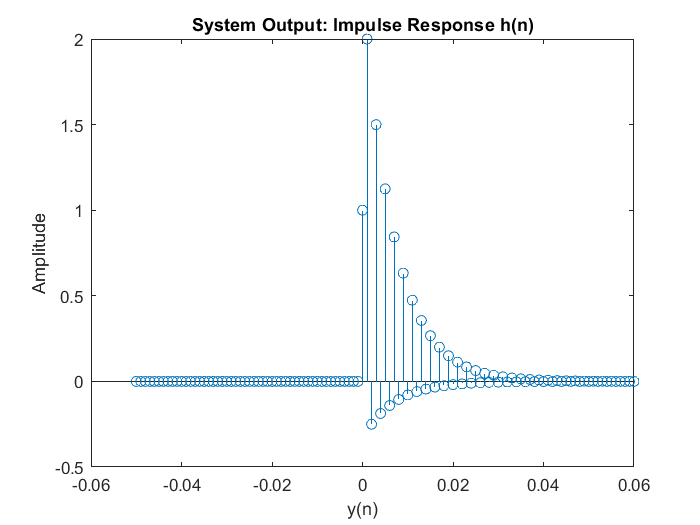


figure('Name','Problem 7D','NumberTitle','off');
stem(n,y);
title('System Output: Impulse Response h(n)');
xlabel('y(n)');
ylabel('Amplitude');

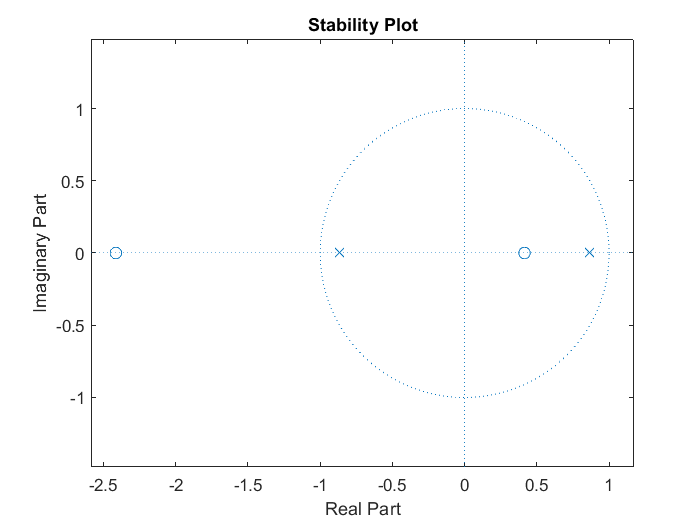



figure('Name','Problem 7D Stability Plot','NumberTitle','off');
zplane(b,a);
title('Stability Plot');

disp('The system is stable because both poles are inside the unit circle');

The system is stable because both poles are inside the unit circle


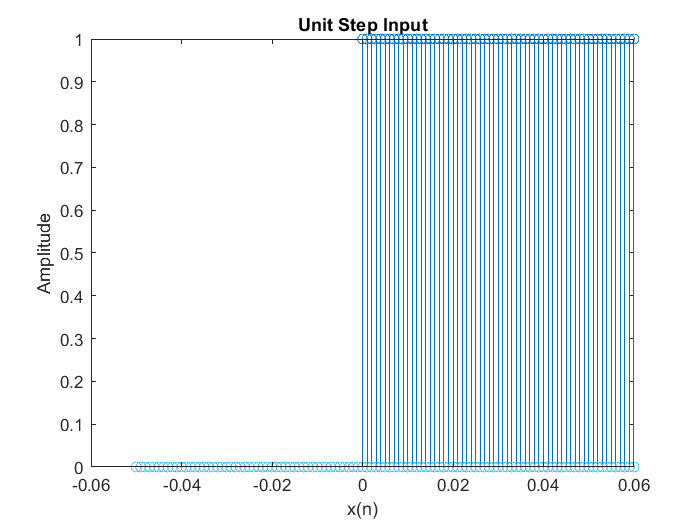







%Problem 7E: Step Response
x=zeros(length(n));   %Setting step input
ind_x=find(n>=0);
x(ind_x)=1;
y = filter(b,a,x); 

figure('Name','Problem 7E','NumberTitle','off');
stem(n,x);
title('Unit Step Input');
xlabel('x(n)');
ylabel('Amplitude');

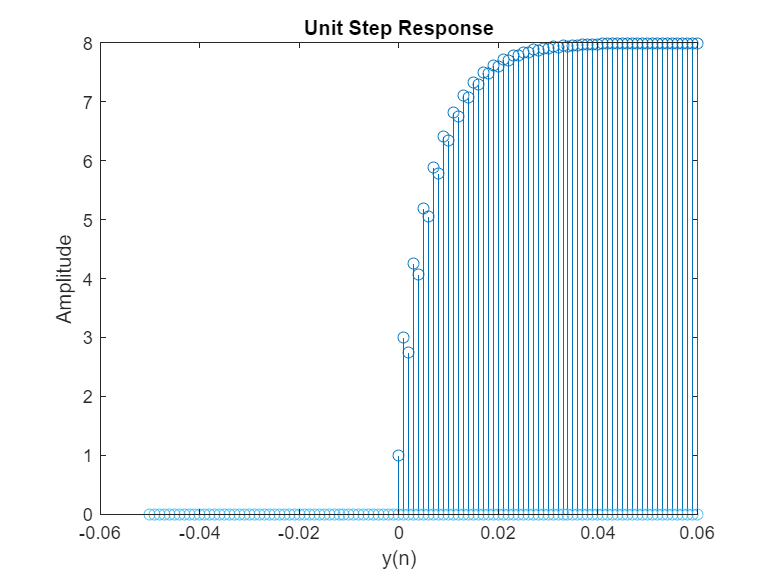


figure('Name','Problem 7E','NumberTitle','off');
stem(n,y);
title('Unit Step Response');
xlabel('y(n)');
ylabel('Amplitude');





%Problem 7G: Energy of Impulse Response
Energy_imp_resp = sum(abs(y).^ 2);
disp('The Energy of the impulse response is: ')

The Energy of the impulse response is: 


Energy_imp_resp(1)

ans = 3.3053e+03